# Fourier Neural Operator for 3D battery heat evolution

This example demonstrates using a 3D Fourier neural operator to learn the heat diffusion on a battery module. The battery design is the same as [this example](https://uk.mathworks.com/help/pde/ug/battery-module-cooling-analysis-and-reduced-order-thermal-model.html), which demonstrates a reduced-order model for the heat diffusion. By comparison, the Fourier neural operator is purely data-driven, and doesn't need precise knowledge of the underlying PDE.

Fourier neural operators require the data to be discretised on a regular grid of points, like those that `meshgrid` and `ndgrid` create. To create some  training data, the example creates the geometry of the battery module and solves the heat equation using [Partial Differential Equation Toolbox](https://uk.mathworks.com/products/pde.html). The solution is given on a finite element mesh. The example interpolates data from the vertices of the finite element mesh to a regular grid using the [`interpolateTemperature`](https://uk.mathworks.com/help/pde/ug/pde.steadystatethermalresults.interpolatetemperature.html) method of the PDE solution, and the [`scatteredInterpolant`](https://uk.mathworks.com/help/matlab/ref/scatteredinterpolant.html) function. At inference time the Fourier neural operator predicts values on this regular grid, which can then be interpolated back onto the mesh vertices using [`griddedInterpolant`](https://uk.mathworks.com/help/matlab/ref/griddedinterpolant.html). 

In this example we vary some of the material and physical properties that define the PDE to create a collection of experiments. The task is to learn the mapping between a set of material and physical properties to the temperature at some future time.

## Specify Battery Module Geometry

The battery module is composed of repeated cells. The helper function `createBateryModuleGeometry` sets up the geometry. The battery is composed of 20 aligned cells, and various parameters specify the shape of those cells.

cellWidth = 150/1000;
cellThickness = 15/1000;
tabThickness = 10/1000;
tabWidth = 15/1000;
cellHeight = 100/1000;
tabHeight = 5/1000;
connectorHeight = 3/1000;

numCellsInModule = 20;

[geomModule,volumeIDs,boundaryIDs,volume,area,ReferencePoint] = ...
    createBatteryModuleGeometry(numCellsInModule, ...
    cellWidth, ...
    cellThickness, ...
    tabThickness, ...
    tabWidth, ...
    cellHeight, ...
    tabHeight, ...
    connectorHeight);

Create an [`femodel`](https://uk.mathworks.com/help/pde/ug/femodel.html) from the geometry and visualize with [`pdemesh`](https://uk.mathworks.com/help/pde/ug/femodel.pdemesh.html).

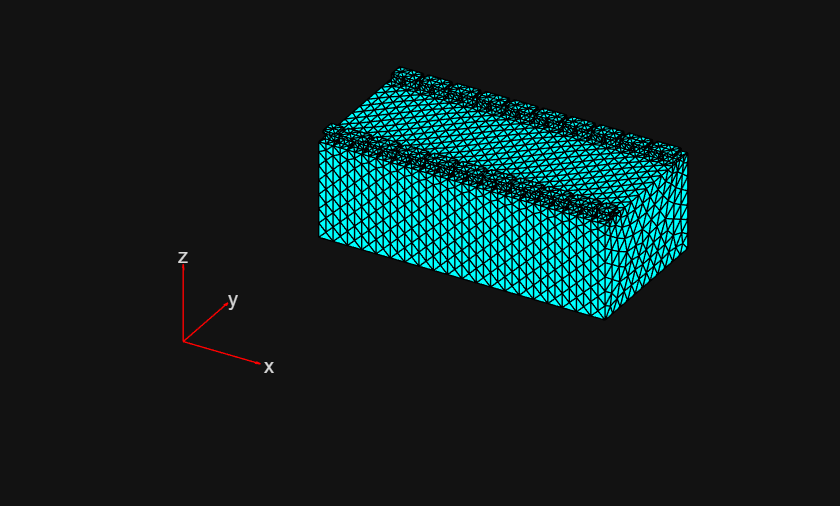

model = femodel(AnalysisType="thermalTransient", ...
    Geometry=geomModule);

model = generateMesh(model);
pdemesh(model)

## Generate simulation data for training

This section sets up the material properties of the model following the [original example](https://uk.mathworks.com/help/pde/ug/battery-module-cooling-analysis-and-reduced-order-thermal-model.html).

cellIDs = [volumeIDs.Cell];
tabIDs = [volumeIDs.TabLeft,volumeIDs.TabRight];
connectorIDs = [volumeIDs.ConnectorLeft,volumeIDs.ConnectorRight];
bottomPlateFaces = [boundaryIDs.BottomFace];

cellThermalCond.inPlane = 80;
cellThermalCond.throughPlane = 2;
tabThermalCond = 386;
connectorThermalCond = 400;

density.Cell = 780;
density.TabLeft = 2700;
density.TabRight = 2700;
density.ConnectorLeft = 540;
density.ConnectorRight = 540;

spHeat.Cell = 785;
spHeat.TabLeft = 890;
spHeat.TabRight = 890;
spHeat.ConnectorLeft = 840;
spHeat.ConnectorRight = 840;

model.MaterialProperties(cellIDs) = ...
    materialProperties(ThermalConductivity= ...
    [cellThermalCond.throughPlane
    cellThermalCond.inPlane
    cellThermalCond.inPlane], ...
    MassDensity=density.Cell, ...
    SpecificHeat=spHeat.Cell);
model.MaterialProperties(tabIDs) = ...
    materialProperties(ThermalConductivity=tabThermalCond, ...
    MassDensity=density.TabLeft, ...
    SpecificHeat=spHeat.TabLeft);
model.MaterialProperties(connectorIDs) = ...
    materialProperties(ThermalConductivity=connectorThermalCond, ...
    MassDensity=density.ConnectorLeft, ...
    SpecificHeat=spHeat.ConnectorLeft);

Let the following 3 properties vary, the ambient temperature, the convection through the front and back of the module, and the heat generated by the cells.

ambientTemperature = linspace(280,300,6);
frontBackConvection = linspace(10,20,6);
heatGeneration = linspace(10,20,6);

Use `ndgrid` to create all combinations of these parameters.

[ambientTemperature, frontBackConvection, heatGeneration] = ndgrid(ambientTemperature, frontBackConvection,heatGeneration);
ambientTemperature = reshape(ambientTemperature,[],1);
frontBackConvection = reshape(frontBackConvection,[],1);
heatGeneration = reshape(heatGeneration,[],1);
params = cat(2,ambientTemperature,frontBackConvection,heatGeneration);

Loop through each parameter combination, specify the appropriate properties on the model, and solve. The simulation here solves up to time $T = 600$, i.e. 10 minutes.

This step can take over 40 minutes to solve all of the instances of the PDE. It is recommended you save the `results` variable if you intend to run this example multiple times using the command `save("results","results","-v7.3")`, using `"-v7.3"` as the file is 1.96GB.

results = cell(size(params,1),1);
for i = 1:size(params,1)
    model.FaceLoad([boundaryIDs(1).FrontFace, ...
        boundaryIDs(end).BackFace]) = ...
        faceLoad(ConvectionCoefficient=params(i,2), ...
        AmbientTemperature=params(i,1));

    nominalHeatGen = params(i,3)/volume(1).Cell;
    model.CellLoad(cellIDs) = cellLoad(Heat=nominalHeatGen);

    model.CellIC = cellIC(Temperature=params(i,1));

    T = 60*10;
    results{i} = solve(model,0:60:T);
end

## Prepare data for training

The geometry in this example can be well approximated by a regular grid discretisation without too much discretisation error. 

Get the bounds of the mesh.

XYZ = geomModule.Mesh.Nodes;
Xmin = min(XYZ,[],2);
Xmax = max(XYZ,[],2);
xmin = Xmin(1,:);
xmax = Xmax(1,:);
ymin = Xmin(2,:);
ymax = Xmax(2,:);
zmin = Xmin(3,:);
zmax = Xmax(3,:);

Create grid coordinates. This example discretises the domain onto a $32 \times 32 \times 32$ grid. 

n = 32;
x = linspace(xmin,xmax,n);
y = linspace(ymin,ymax,n);
z = linspace(zmin,zmax,n);
[X,Y,Z] = meshgrid(x,y,z);
Xflat = reshape(X,[],1);
Yflat = reshape(Y,[],1);
Zflat = reshape(Z,[],1);

At each $(x_i,y_i,z_i)$ on the grid there are the 3 coordinate features, and 3 material and physical properties that we let vary above, the ambient temperature $T_i$, the convection $P_i$ and the heat generation $Q_i$ at the point $(x_i, y_i, z_i)$. These will be the input features $u$. The target $v$ is the temperature at $(x_i,y_i,z_i)$ at the end time of the simulation. 

For a given instance of the parameters, `params(i,:)` corresponds to an ambient temperature $T_i$, convection $P_i$ and heat generation $Q_i$ specified at the chosen vertices above. We can then consider $u_i(x,y,z) = (x,y,z,T_i(x,y,z),P_i(x,y,z),Q_i(x,y,z))$ as a function representation of the input data, where $T_i, P_i, Q_i$ have been extended to take the value $0$ at all vertices besides those specified above. In this sense each of `results{i}` contains to a discretisation of $u_i$ onto the mesh vertices. The temperature $v_i$ can be considered similarly.

We can interpolate the mesh discretisation onto a regular grid or $32 \times 32 \times 32$ points. This will give us a multi-dimensional array `U` where `U(i,j,k,p,n)` corresponds to the `p`-th feature of the `n`-th observation at point $(x_i,y_j,z_k)$. 

The target temperature can be interpolated using [`interpolateTemperature`](https://uk.mathworks.com/help/pde/ug/pde.steadystatethermalresults.interpolatetemperature.html)`.T`he other parameters are interpolated using [`scatteredInterpolant`](https://uk.mathworks.com/help/matlab/ref/scatteredinterpolant.html). For the `scatteredInterpolant` approach, we use [`findNodes`](https://uk.mathworks.com/help/pde/ug/pde.femesh.findnodes.html) to get the node indices where material properties were specified, and interpolate a function defined to have the specified property value at those nodes, and $0$ elsewhere. The ambient temperature is treated as a constant feature across space.

The `interpolateTemperature` function may return `NaN` at coordinates that are actually extrapolations. This occurs because the grid coordinates may lie outside the geometry. In this case this is due to the tabs on the battery module which extend in the $z$-dimension. The approach here is to impute the `NaN` values by projecting up from the last non `NaN` value in the $z$ dimension.

As above, this interpolation step may take some time and it is advisable to save the data with a command such as `save("interpolated","U","V")` if you intend to run this example multiple times.

U = zeros(n,n,n,6,size(params,1));
V = zeros(n,n,n,1,size(params,1));

for i = 1:size(params,1)
    result = results{i};

    % Interpolate the final temperature onto the regular grid
    tidx = length(result.SolutionTimes);
    T = result.interpolateTemperature(Xflat,Yflat,Zflat,tidx);
    T = reshape(T,n,n,n);

    % Find the nan-s and impute along the z-dimension
    nans = isnan(T);
    for j = 1:n
        for k = 1:n
            idx = find(nans(j,k,:),1);
            T(j,k,idx:end) = T(j,k,idx-1);
        end
    end

    % Specify the target
    V(:,:,:,:,i) = T;

    % Specify coordinate features as input.
    U(:,:,:,1:3,i) = cat(4,X,Y,Z);

    % Specify functions for the convection discretised
    % onto the nodes.
    % Get the nodes for the face loads
    convection = zeros(size(result.Mesh.Nodes,2),1);
    boundary = findNodes(result.Mesh,"region",Face = [boundaryIDs(1).FrontFace,boundaryIDs(end).BackFace]);
    convection(boundary) = params(i,2);

    % Interpolate the convection to the grid points
    F = scatteredInterpolant(result.Mesh.Nodes.', convection);
    convectionGrid = F(X,Y,Z);

    % Similarly interpolate the heat generation.
    heatGen = zeros(size(result.Mesh.Nodes,2),1);
    cells = findNodes(result.Mesh,"region",Cell=cellIDs);
    heatGen(cells) = params(i,3);
    G = scatteredInterpolant(result.Mesh.Nodes.',heatGen);
    heatGenGrid = G(X,Y,Z);

    % Specify the ambient temperature as a constant feature, and append the
    % convection and heat generation interpolated features.
    ambientTemperature = repmat(params(i,1),size(convectionGrid));
    U(:,:,:,4:6,i) = cat(4,ambientTemperature,convectionGrid,heatGenGrid);
end

## Train a Fourier neural operator

This section defines a Fourier neural operator for this 3D problem using `spectralConvolution3dLayer`. We use a slight modification of the original Fourier layer described in section 4 of [[1](https://openreview.net/forum?id=c8P9NQVtmnO)] to use a `layerNormalizationLayer `in the Fourier layer as motivated by section 3.4 of [[2](https://openreview.net/forum?id=AWiDlO63bH)]. Residual connections around the Fourier layers are also used. The data is linearly scaled onto $[0,1]$ using feature-wise scales.

This training is quite demanding on GPU compute, a minibatch size of 8 was required when the model had hidden size $64$ and $4$ layers, and the input was $32 \times 32 \times 32$, when using a 12GB Titan Xp GPU. Training for 1000 epochs took 14 hours. As above it is advisable to save the trained network with a command such as `save("trained_model","net")` if you intend to re-use the model or re-run this example.

idx = randperm(size(U,5));
numTrain = round(0.8*size(U,5));
idxTrain = idx(1:numTrain);
idxVal = idx(numTrain+1:end);
Uval = U(:,:,:,:,idxVal);
Utrain = U(:,:,:,:,idxTrain);
Vval = V(:,:,:,:,idxVal);
Vtrain = V(:,:,:,:,idxTrain);

umax = max(Utrain,[],[1,2,3,5]);
umin = min(Utrain,[],[1,2,3,5]);
vmax = max(Vtrain,[],[1,2,3,5]);
vmin = min(Vtrain,[],[1,2,3,5]);

epsilon = 0;
Unorm = (Utrain - umin)./(umax - umin + epsilon);
Vnorm = (Vtrain - vmin)./(vmax - vmin + epsilon);
Uval = (Uval - umin)./(umax - umin + epsilon);
Vval = (Vval - vmin)./(vmax - vmin + epsilon);

hiddenSize = 64;
numModes = 4;
nlayers = 4;

function layer = fourier3dLayer(numModes,hiddenSize,args)
arguments
    numModes
    hiddenSize
    args.Activation = @geluLayer
end
layers = [
    identityLayer(Name="in")
    spectralConvolution3dLayer(numModes,hiddenSize)
    additionLayer(2,Name="add")
    layerNormalizationLayer
    args.Activation()];
net = dlnetwork(layers,Initialize=false);
net = net.addLayers(convolution3dLayer(1,hiddenSize,Name="conv"));
net = connectLayers(net,"conv","add/in2");
net = connectLayers(net,"in","conv");
layer = networkLayer(net);
end

function layer = residualLayer(layer)
layers = [
    identityLayer(Name="in")
    layer
    additionLayer(2,Name="add")];
net = dlnetwork(layers,Initialize=false);
net = connectLayers(net,"in","add/in2");
layer = networkLayer(net);
end

layers = [
    inputLayer([n,n,n,size(U,4),NaN],'SSSCB',Name="in")
    convolution3dLayer(1,2*hiddenSize,Padding="same")
    layerNormalizationLayer
    geluLayer
    convolution3dLayer(1,hiddenSize,Padding="same")
    repmat(residualLayer(fourier3dLayer(numModes,hiddenSize)),nlayers,1)
    convolution3dLayer(1,2*hiddenSize,Padding="same")  
    layerNormalizationLayer
    geluLayer
    convolution3dLayer(1,size(V,4),Padding="same")];

net = dlnetwork(layers,Initialize=false);

opts = trainingOptions("adam",...
    Plots="training-progress",...
    MiniBatchSize = 8,...
    InputDataFormats="SSSCB",...
    TargetDataFormats="SSSCB",...
    Shuffle="every-epoch",...
    ValidationData = {Uval,Vval},...
    ValidationFrequency=100,...
    MaxEpochs = 1000);

net = trainnet(Unorm,Vnorm, net, "l2loss" ,opts);

Here is what the training plot looked like:

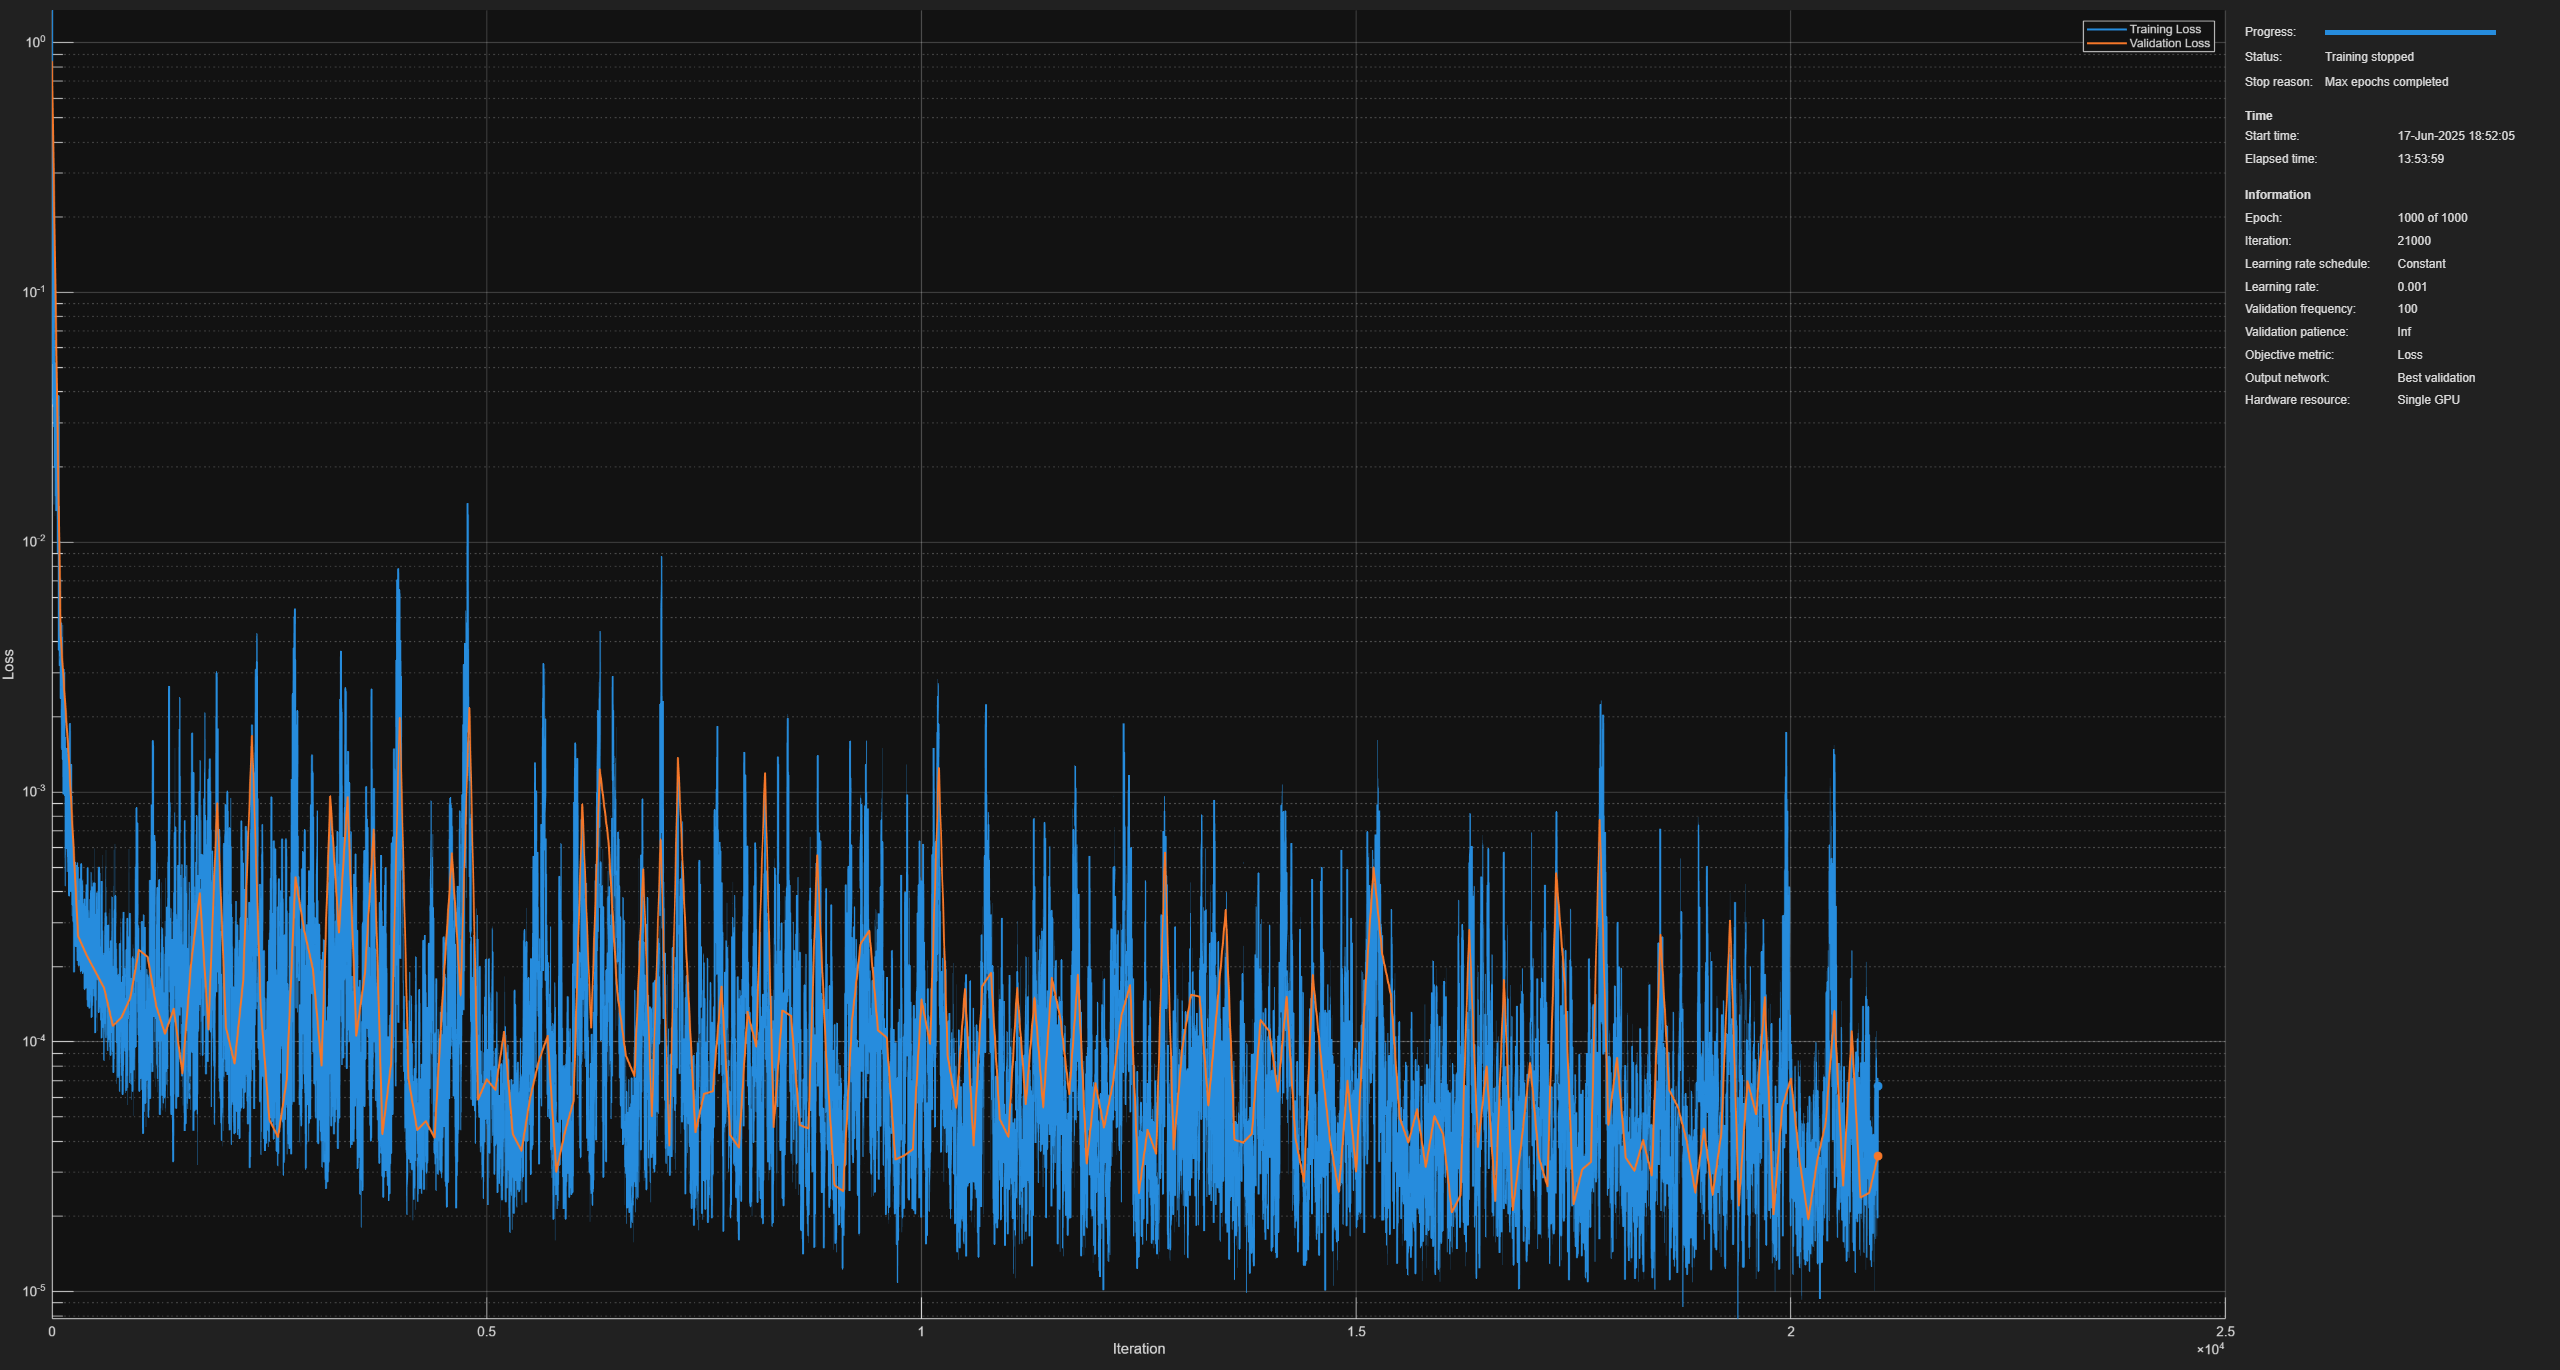

## Test the model

The model is tested on the validation data below using [`minibatchpredict`](https://uk.mathworks.com/help/deeplearning/ref/minibatchpredict.html). To compare to the true data the model output has to be interpolated back onto the mesh using `griddedInterpolant`.

startTime = tic;
pred = minibatchpredict(net,Uval);
endTime = toc(startTime)

endTime = 4.9331

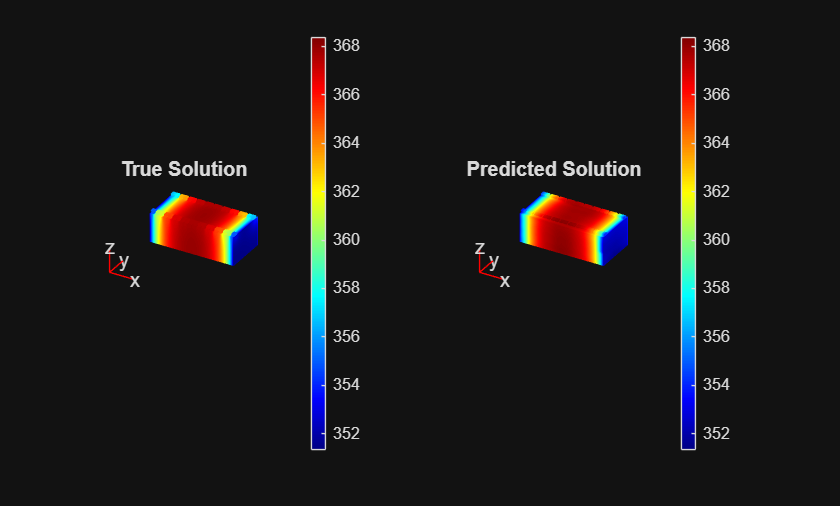


% Inverse the scaling applied before training.
pred = pred.*(vmax - vmin + epsilon) + vmin;

% Choose a random validation observation to visualize.
i = randi([1,numel(idxVal)]);

% griddedInterpolant wants the data to be in ndgrid format, which requires
% the following permutation.
P = [2,1,3];
result = results{idxVal(i)};
interpolation = griddedInterpolant(...
    permute(X,P),...
    permute(Y,P),...
    permute(Z,P),...
    permute(pred(:,:,:,:,i),P),...
    'spline');
interpolatedPrediction = interpolation(result.Mesh.Nodes.');
trueSolution = result.Temperature(:,end);
diffMesh = abs(interpolatedPrediction - trueSolution);

% Get limits
mintemp = min([trueSolution; interpolatedPrediction]);
maxtemp = max([trueSolution; interpolatedPrediction]);

figure
subplot(1,2,1)
pdeplot3D(result.Mesh, ColorMapData = trueSolution, FaceAlpha = 1);
clim([mintemp,maxtemp]);
title("True Solution")
subplot(1,2,2);
pdeplot3D(result.Mesh, ColorMapData = interpolatedPrediction, FaceAlpha = 1);
clim([mintemp,maxtemp]);
title("Predicted Solution")

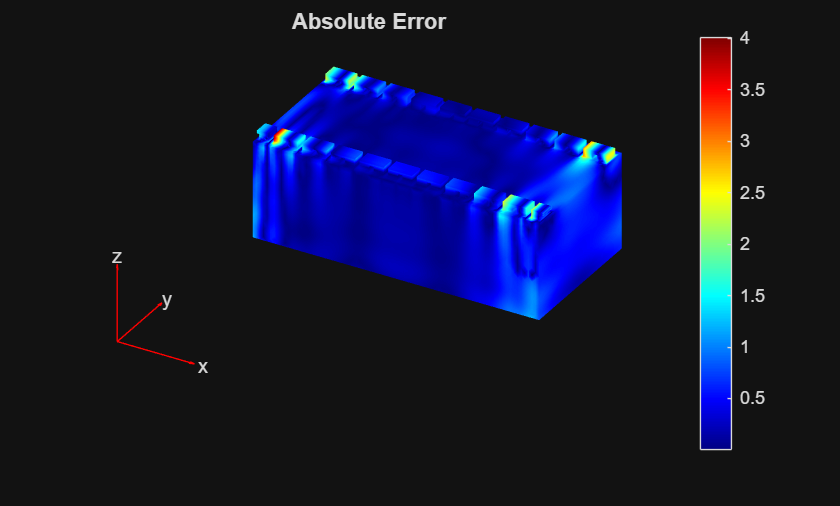


figure
pdeplot3D(result.Mesh, ColorMapData = diffMesh, FaceAlpha = 1);
title("Absolute Error")

The model and interpolation appears to have a $<1\%$ error. Often the largest errors are on the battery tabs which may be due to the discretisation errors from interpolating the mesh to a grid and back again. It takes roughly 5 seconds for `minibatchpredict` to make inferences for the 43 validation observations, about 0.12 seconds each. This is close to 100x faster than using the original finite element solver. 

It should be noted that the [original example](https://uk.mathworks.com/help/pde/ug/battery-module-cooling-analysis-and-reduced-order-thermal-model.html) demonstrates how to use a built-in reduced-order model for this problem that can solve the underlying PDE accurately and quickly. One of the advantages of the Fourier neural operator approach here is that we can very quickly get approximate solutions for many different input parameters. Another possibility is that the Fourier neural operator supports the "zero-shot super resolution" as described in section 5.4 of [[1](https://openreview.net/pdf?id=c8P9NQVtmnO)], which can be useful for problems with more complicated behaviours with finer structurs in the solution. Further the Fourier neural operator is purely data-driven, and may be applied to a wide variety of PDE data.

It is also important to note that the interpolation method used here to interpolate the mesh data onto a grid, and from the grid predictions back to the mesh, introduces discretisation errors. For more complicated geometries it may be difficult to trade off large discretization errors and the memory usage of a finer grid resolution that can better capture such geometries. In such cases there are other approaches that have been proposed for working with Fourier neural operators and non-grid data.

- GINO [3] uses graph neural operators as encoders and decoders, since graph neural operators can operator on both input data on a mesh, and queried from gridded data back onto a mesh. In this sense the graph neural operator can be used as an encoder and decoder to a latent space where the data lies on a grid, in this latent space a regular Fourier neural operator can be used.

- Geo-FNO [4] uses a diffeomorphism on the input geometry to deform the input coordinates onto a regular grid. In some cases the original coordinates may be suitably structured to specify this diffeomorphism. In other cases, the diffeomorphism is learnt via a neural network. Once the geometry is deformed onto a regular grid, an adapted version of the Fourier neural operator can be used. Then the diffeomorphism is inverted to output the predictions on the original geometry.

### References

[1] Li, Zongyi, Nikola Borislavov Kovachki, Kamyar Azizzadenesheli, Burigede Liu, Kaushik Bhattacharya, Andrew Stuart, and Anima Anandkumar. 2021. "Fourier Neural Operator for Parametric Partial Differential Equations." In *International Conference on Learning Representations*. [https://openreview.net/forum?id=c8P9NQVtmnO](https://openreview.net/forum?id=c8P9NQVtmnO).

[2] Kossaifi, Jean, Nikola Borisalov Kovachki, Kamyar Azizzadenesheli, and Anima Anandkumar. 2024. "Multi-Grid Tensorized Fourier Neural Operator for High-Resolution PDEs." *Transactions on Machine Learning Research*. [https://openreview.net/forum?id=AWiDlO63bH.](https://openreview.net/forum?id=AWiDlO63bH.)

[3] Li, Zongyi, Nikola Borislavov Kovachki, Chris Choy, Boyi Li, Jean Kossaifi, Shourya Prakash Otta, Mohammad Amin Nabian, Maximilian Stadler, Christian Hundt, Kamyar Azizzadenesheli, and Anima Anandkumar. 2023. “Geometry-Informed Neural Operator for Large-Scale 3D PDEs.” Paper presented at the *Thirty-seventh Conference on Neural Information Processing Systems*. [https://openreview.net/forum?id=86dXbqT5Ua](https://openreview.net/forum?id=86dXbqT5Ua).

[4] Li, Zongyi, Daniel Zhengyu Huang, Burigede Liu, and Anima Anandkumar. 2023. "Fourier Neural Operator with Learned Deformations for PDEs on General Geometries." *Journal of Machine Learning Research 24, no. 388*: 1–26. [http://jmlr.org/papers/v24/23-0064.html](http://jmlr.org/papers/v24/23-0064.html).